# Kalman FIlter

## References

[YouTube - Dr. Dhane Ross](https://www.youtube.com/watch?v=qCZ2UTgLM_g&t=24s)

[Kalman_and_Bayesian_Filters](matlab:open('..\..\..\..\Library\System Control\Theory\Kalman_and_Bayesian_Filters_in_Python.pdf'))

## KF Algorithm Overview


$$\underline{\text{Linear state model :}} \\
\text{state: } x_{k+1} = A\cdot x_{k} + w_k  \\
\text{measurment: } z_{k+1} = H x_{k} + v_k  \\

x_k = \text{state variable (n x1 column vector)} \\
z_k = \text{measurment ( m x 1 column vector)} \\
A = \text{state transition matrix( n x n matrix)} \\
H = \text{state -to-measurment matrix( m x n matrix)} \\
w_k = \text{state transition noise (n x 1 column vector)} \\
v_k = \text{measurment noise (m x 1 column vector)} \\
\underline{\text{Covariance of the noise:}} \\
Q = \text{covariance matrix of  } w_k \text{ (n x n diagonal matrix)  } \\
R = \text{covariance matrix of  } v_k \text{ (m x m diagonal matrix)  } \\$$
 

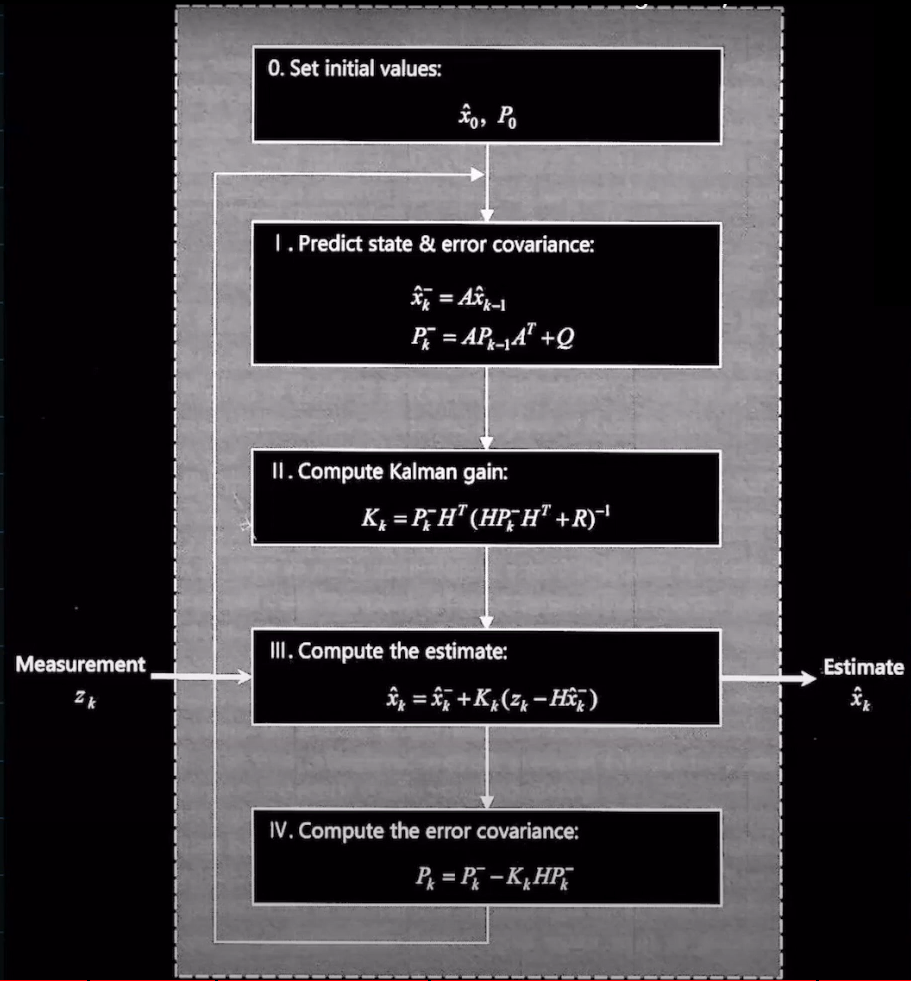

## KF and 1st Order LPF


$$III. \\
\matrix{ \hat{x}_k & = & \hat{x}_k^- + K_k \big (z_k - H \hat{x}_k^- \big)  \cr
& = &\big( I - K_k H) \hat{x}_k^- + K_k z_k }\\

\text{for state size, n = 1, H=1:} \\
\quad \hat{x}_k = \big( 1 - K_k \big) \hat{x}_k^- + K_k z_k \\

\text{Let`s choose} \alpha = 1 - K_k \\
\Rightarrow \hat{x}_k = \alpha \hat{x}_k^- + (1-\alpha)z_k  \\
\text{its lookes like a Low Pass FIlter, when \alpha\ is variyng each k}$$
